# Cell Morphing - Example

## Pre-processing

### Importing the data

We import the segmentation from a `.tif` file. These can have pages, and the function `segmentation.m` takes care of interpreting them.

[im_cells, im_groups, im_histology, resolution] = segmentation('coins.tif_layered');

Let's also see what we have imported to verify everything is as intended.

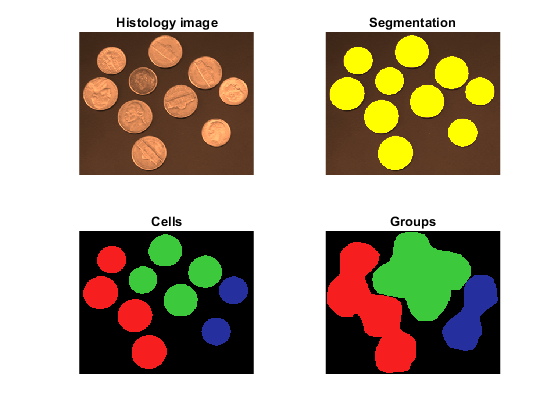

figure();
subplot(2,2,1);
imshow(im_histology);
title('Histology image');
subplot(2,2,2);
imshow(imoverlay(im_histology, im2bin(im_cells)));
title('Segmentation');
subplot(2,2,3);
imshow(im_cells);
title('Cells');
subplot(2,2,4);
imshow(im_groups);
title('Groups');

### Resizing

Last, upscaling the image allows for more fine-grained morphing, but at a higher computational effort.

upscale = 1;
size0 = size(im_cells); % before
im_cells  = imresize(im_cells,  upscale, 'nearest');
im_groups = imresize(im_groups, upscale, 'nearest');
im_histology = imresize(im_histology, upscale, 'nearest');
resolution = resolution * upscale;
size1 = size(im_cells); % after
fprintf('Image size [w, h] after import: [%d, %d]\n', size0(1:2))

Image size [w, h] after import: [246, 300]


fprintf('Image size [w, h] after resize: [%d, %d]\n', size1(1:2))

Image size [w, h] after resize: [246, 300]


% don't run this section repeatedly, it will keep resizing the image!

### Conversion

Morphing can only be done on binary images.

bw_cells  = im2bin(im_cells );
bw_groups = im2bin(im_groups);

We also extract and store the colours for later use.

colours = unique(reshape(im_groups, [], 3), 'rows');
fprintf('  R   G   B\n');

  R   G   B


fprintf('%3d %3d %3d\n', colours(:,1),colours(:,2),colours(:,3));

  0  37  60
246   0  48
202  30   0
158  60  30


## Core algorithm

### Thicken

The individual cells can be thickened. This adds a pixel layer to the outside of each object every iteration, unless doing so would cause neighbouring objects to merge. The group boundaries are respected by clipping the cell to the group.

nThick = 5;
tic
[bw_cells_thick, bw_groups_thick, nThick] = thicken(bw_cells, bw_groups, nThick);
toc

Elapsed time is 0.733417 seconds.


### Shrink

We can also shrink the cells (and groups). This reduces the objects towards a point.

nThin = [2, 0]; % do the cells but not the groups
tic
[bw_cells_thin, bw_groups_thin] = shrink(bw_cells_thick, bw_groups_thick, nThin);
toc

Elapsed time is 0.173789 seconds.


## Post-processing

After morphing has finished, the individual objects can be extracted and converted into polygons (represented by the MATLAB class `polyshape`).

% convert to polygons (in image coordinates)
tic
cells_ij  = im2polys(bw_cells_thin);
groups_ij = im2polys(bw_groups_thin);
toc

Elapsed time is 0.120443 seconds.


### Analysis

The conversion from image to polygon slightly shrinks each object. Here we calculate the volume (or rather, area) fraction of the objects.

volume = table('Size', [2, 2], 'VariableTypes', {'double', 'double'}, 'RowNames', {'cells', 'groups'}, 'VariableNames', {'image', 'polygons'});
volume.Properties.Description = 'volume fraction';

vol = prod(size(bw_cells, 1:2));
volume.image = [sum(bw_cells, 'all'); sum(bw_groups, 'all')]/vol*100;
volume.polygons = [sum([cells_ij.area]); sum([groups_ij.area])]/vol*100;

disp(volume);

              image     polygons
              ______    ________

    cells     31.373     32.394 
    groups    51.993     51.041 



### Display

One quick look at the results before we finish off.

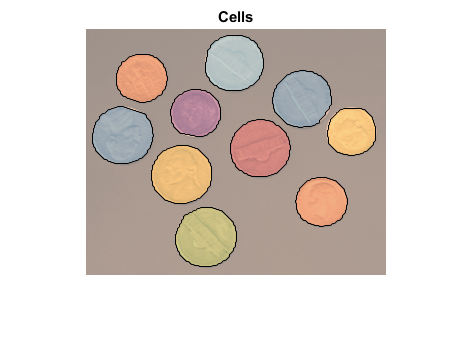

figure();
h = imshow(im_histology);
h.AlphaData = 0.5; % make slighly transparent
hold('on');
plot(cells_ij);
box('on');
title('Cells');
axis ij

### Transformation

The polygons are still in image coordinates. For simplicity, we simply subtract 1 (so that the origin is at zero) and multiply image coordinates by the resolution of the image.

% transform y to flip (1:1:H -> H:-1:1)
height = size(im_histology, 1); % rows
cells_ij_flipped = arrayfun(@(p) polyshape(p.Vertices.*[1, -1]+[0, height+1]), cells_ij);

% scale in size
m_per_px = 1/mean(resolution); % resolution is px_per_m
cells_xy = cells_ij_flipped.scale(m_per_px);

However, consider the following caveats with this approach:

- Image coordinates are pixel-centered, thereby reducing the area of the polygons.

- Image coordinates have a range of `[1, H], `essentially making the image `H-1` high.

### Export

Now we just need to save the data. We use the common VTK (legacy) format, that can be viewed for example in ParaView.

write_poly('coins.vtk', cells_xy);